# Classify Pills Using Different Deep Learning Networks and Analyze the Results

This example shows you how to train and use 4 different types of deep learning networks to classify pills based on the type of defect and analyze the reason for the decision.

## Dataset

This example uses the pillQC dataset. The dataset contains images from three classes: `normal` images without defects, `chip` images with chip defects in the pills, and `dirt` images with dirt contamination. Two more defect classes were added virtually by modifying the normal images: `discoloration` images with discolored pills and `text` images of pills with text on them. Including the virtually created classes, the data set contains

- 149 `normal` images

- 43 `chip` images

- 138 `dirt` images

- 131 `discoloration` images

- 149 `text` images. 

Example images for each class are shown below in the order: normal, dirt, chip, discoloration and text.

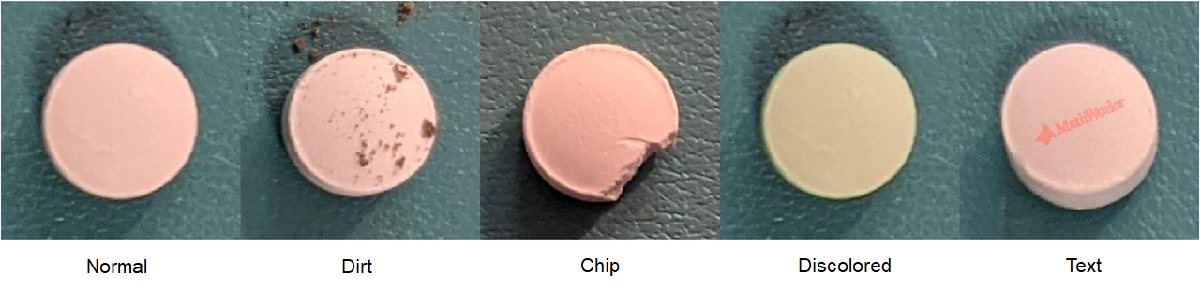

## Load and Preprocess Network and Data

### Load Data

Create an [`imageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) that reads and manages the image data. Label each image as `chip, dirt, discoloration, normal, or text` according to the name of its directory.

SelectDataResolution = "images_128";
imageDir = fullfile(pwd,"Images_PillDataset",SelectDataResolution);
imds = imageDatastore(imageDir,IncludeSubfolders=true,LabelSource="foldernames");

defectClasses = ["chip","dirt","discoloration","normal","text"];
numClasses = numel(defectClasses);

imds

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Images_PillDataset\images_128\chip\chip0001.jpg';
                              ' ...\Images_PillDataset\images_128\chip\chip0002.jpg';
                              ' ...\Images_PillDataset\images_128\chip\chip0003.jpg'
                               ... and 607 more
                              }
                     Folders: {
                              ' ...\3-DefectDetectionAndClassification\Images_PillDataset\images_128'
                              }
                      Labels: [chip; chip; chip ... and 607 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


### Partition Data into Training, Calibration, and Test Sets

Use [`splitEachLabel`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) to split the dataset into training (70%), validation (20%) and test (10%). 

- Training - used to train the network

- Validation - check the accuracy of the dataset during training

- Test - evaluate the final network against a new dataset

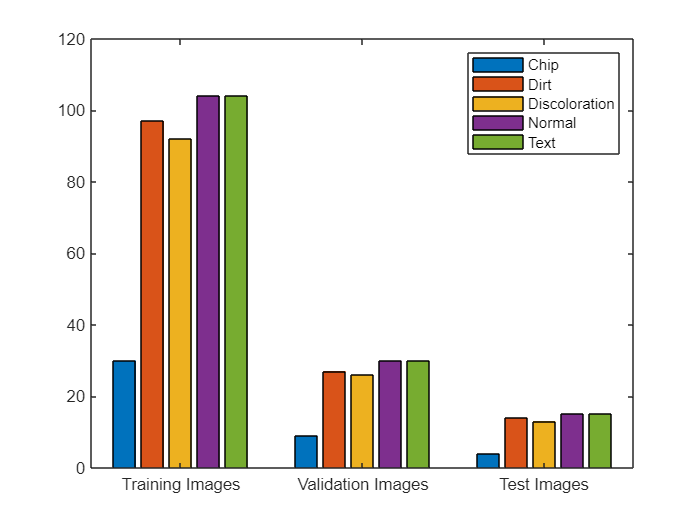

numTrain = 0.7;
numVal = 0.2;
[imdsTrain,imdsVal,imdsTest] = splitEachLabel(imds,numTrain,numVal,"randomized");

displayImdsLabelSplit(imdsTrain,imdsVal,imdsTest)

### Create Network

This demo contains 4 different deep learning networks of varying size and complexity that are modified to classify the different types of pills:

- [SqueezeNet (68 layers, 4.42 MB)](https://www.mathworks.com/help/deeplearning/ref/squeezenet.html)

- [MobileNet-v2 (154 layers, 12.6 MB)](https://www.mathworks.com/help/deeplearning/ref/mobilenetv2.html)

- [GoogLeNet (144 layers, 25 MB)](https://www.mathworks.com/help/deeplearning/ref/googlenet.html)

- [ResNet-50 (177 layers, 91 MB)](https://www.mathworks.com/help/deeplearning/ref/resnet50.html)

The modifications to the networks are made using helper functions that are found in the "HelperFiles" folder. You can look open `pretrainedNetworkSelector.m` for more details.

To avoid training, pretrained versions of these networks can be used by disabling `enableNetworkTraining`. 

enableNetworkTraining = false;
networkSelector = "googlenet";

[net,lgraph] = pretrainedNetworkSelector(networkSelector,enableNetworkTraining,numClasses);

function lgraph = modifyGooglenet(lgraph,numClasses)

newLearnableLayer = fullyConnectedLayer(numClasses, "Name","new_fc","WeightLearnRateFactor",10,"BiasLearnRateFactor",10);
lgraph = replaceLayer(lgraph,"loss3-classifier",newLearnableLayer);        
newClassLayer = classificationLayer("Name","new_classoutput");
lgraph = replaceLayer(lgraph,"output",newClassLayer);


analyzeNetwork(net)

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


### Augment Training Data

Augment the training data using the [`imageDataAugmenter`](https://www.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html) function with random 90 degree rotations, and flipping the image horizontally and vertically. Augmention modifies the data randomly as specified which can avoid overfitting the network to the training data. 

All data in the training, validation and test data is resized to the networks input size.

dsTrainAugmenter = imageDataAugmenter("RandRotation",@() randi([0 3])*90,"RandXReflection",true,"RandYReflection",true);
dsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,"DataAugmentation",dsTrainAugmenter);

dsVal = augmentedImageDatastore(inputSize(1:2),imdsVal);

dsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

disp("Section completed running")

Section completed running


## Train and Test Network

### Train Network

If the `enableNetworkTraining` option is enabled, the modified deep learning network is trained using the training and validation data.

For this, set the training options using the [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function. The `setTrainingProperties` function is a custom function that sets some of the training options based on the selected network. Train the model using the [`trainNetwork`](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html) function.

If the `enableNetworkTraining` option is disabled, the pretrained networks is set to the `networkTrained` variable.

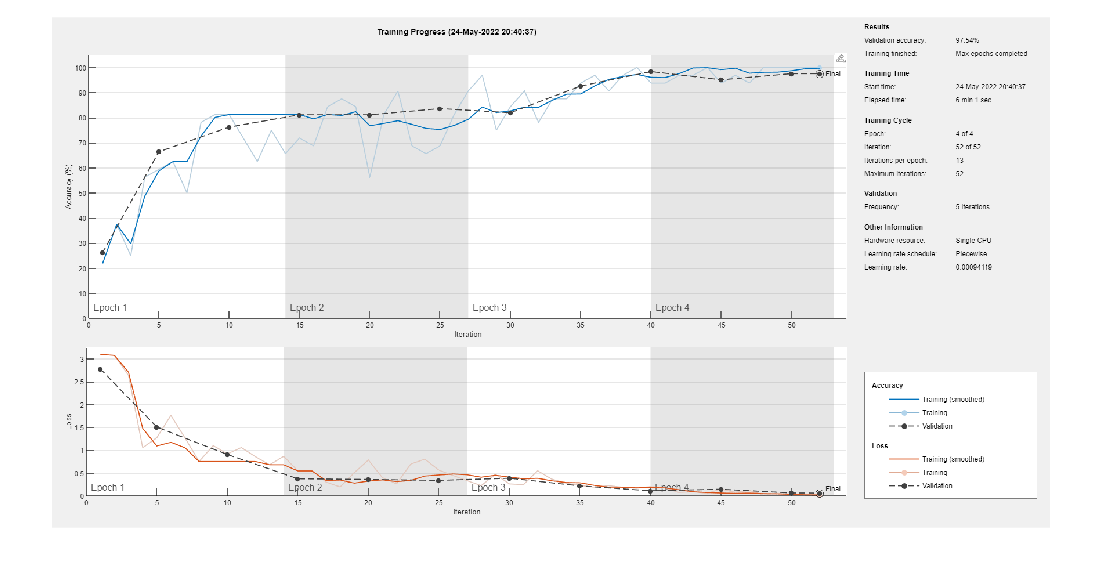

if enableNetworkTraining
    trainingProperties = setTrainingProperties(networkSelector);
    options = trainingOptions("sgdm", "InitialLearnRate",1e-3, "MaxEpochs",trainingProperties.MaxEpochs, "MiniBatchSize",32, "Shuffle","every-epoch", ...
        "Verbose",true, "ValidationData",dsVal, "ValidationFrequency",5, "Plots","training-progress",...
        "LearnRateSchedule","piecewise","LearnRateDropFactor",0.98,"LearnRateDropPeriod",1)

    networkTrained = trainNetwork(dsTrain,lgraph,options);
else
    networkTrained = net;
    displayTrainingProgress(networkSelector);
end

### Test Network

**To Do:** Use the `classify` command to evaluate the test dataset. (Doc Link: [classify](https://www.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html)). Name the outputs "YPred" and "scores"

% ADD CODE HERE
[YPred,scores] = classify(networkTrained,dsTest);

YTrue = imdsTest.Labels;

disp("Section completed running")

Section completed running


### Display Sample Results

Once the test dataset is classified, display some of the images. Correctly classified images have a green title while incorrectly classified images have a red title.

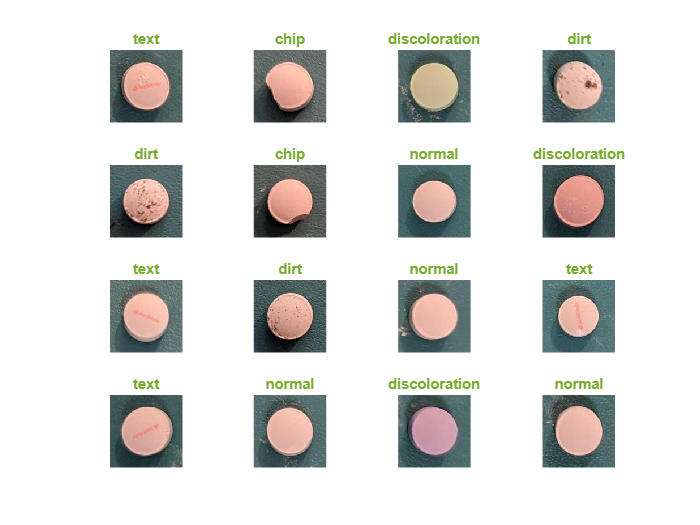

imgMax = size(dsTest.Files,1);
imgNum = 16;
idx = randperm(numel(imdsTest.Files),imgNum);

displayTestImages(imdsTest,YPred,YTrue,imgNum,idx)

## Analyze Network

The next step is to analyze how the network performed.

### Confusion Matrix

Calculate the performance of the network by comparing the true classes against the predicted classes in a confusion matrix using [confusionmat](https://www.mathworks.com/help/deeplearning/ref/confusionmat.html). Display the results using the [confusionchart](https://www.mathworks.com/help/deeplearning/ref/confusionchart.html) function. The values across the diagonal indicate correct classifications.

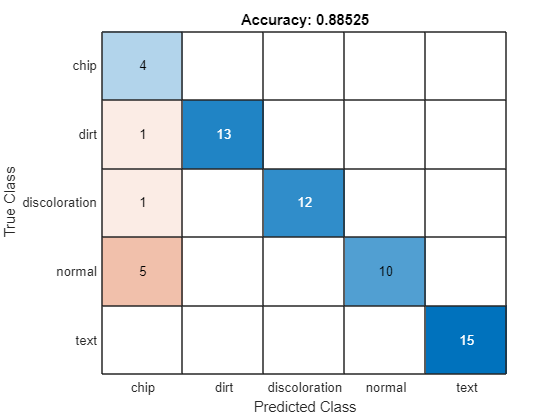

maxIdxCorrect = 10

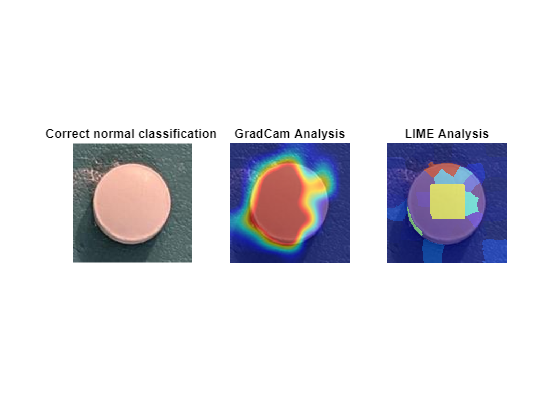

maxIdxIncorrect = 5

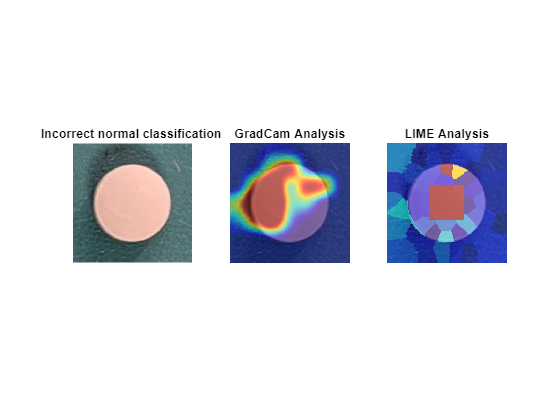

accuracy = mean(YPred == YTrue);
M = confusionmat(YTrue,YPred);
figure
confusionchart(M,defectClasses)
title("Accuracy: "+accuracy)

## Summary

In summary, this demo uses different deep learning networks to classify pills based on the defects they have. To do this, we:

- Loaded the pill dataset into a [datastore](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html), [split](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) the data into train, validation and test datasets and [augment](https://www.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html) them. We also selected a deep learning network and modified it for this demo (transfer learning).

- We [trained](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html) and [tested](https://www.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html) the network against the test dataset.

- Finally, we analyzed the results using a [confusion matrix](https://www.mathworks.com/help/deeplearning/ref/confusionmat.html), [Grad-CAM](https://www.mathworks.com/help/deeplearning/ref/gradcam.html) and [LIME](https://www.mathworks.com/help/deeplearning/ref/imagelime.html).

*Copyright 2022 The MathWorks, Inc.*